**Parameters**

% M matrix -> it's symmetric
m1 = 96.8;
m2 = -3.57;
m3 = -3.57;
m4 = 0.258;

% C matrix
c1 = 0;
c2 = -50.8;
c3 = 0.436;
c4 = 2.20;

% K0 matrix
k11 = -901.0;
k12 = 35.17;
k13 = 35.17;
k14 = -12.03;

% K2 matrix
k21 = 0;
k22 = -87.06;
k23 = 0;
k24 = 3.50;

**State Space representation**

V = 6.1;
a1 = k11+k21*V^2;
a2 = k12+k22*V^2;
a3 = k13+k23*V^2;
a4 = k14+k24*V^2;

A1 = m2/(m2*m3-m1*m4);
A2 = m4/m2;
A3 = m1/m2;

A = [
    0                                     0                             1                               0;
    0                                     0                             0                               1;
    A1*A2*a1-A1*a3                     A1*A2*a2-A1*a4                 A1*A2*c1*V-A1*c3*V                  A1*A2*c2*V-A1*c4*V;
    -A1*A2*A3*a1+A1*A3*a3-a1/m2     -A1*A2*A3*a2+A1*A3*a4-a2/m2     -A1*A2*A3*c1*V+A1*A3*c3*V-c1*V/m2     -A1*A2*A3*c2*V+A1*A3*c4*V-c2*V/m2;
];

B = [
    0;
    0;
    A1;
    -A3*A1
];

C = [1 0 0 0];
D = 0;

sys_ss = ss(A, B,C,D)

sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3    8.741    33.09  -0.7764     2.62
   x4   -15.36   -0.227   -21.05   -15.76
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.2919
   x4   7.915
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



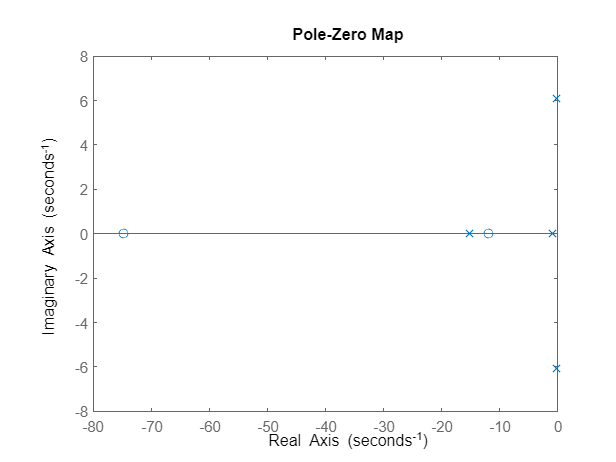

pzmap(sys_ss)

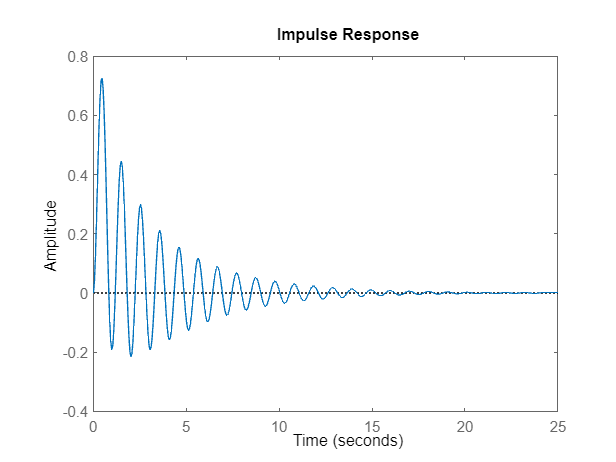

impulse(sys_ss)

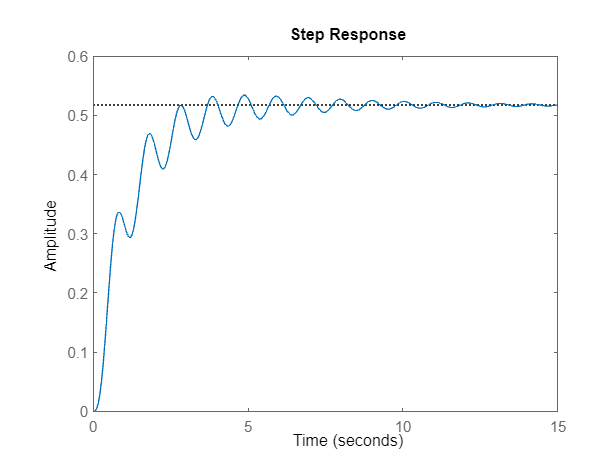

step(sys_ss)

pole(sys_ss)

ans =   -0.9063 + 0.0000i
  -0.2564 + 6.0736i
  -0.2564 - 6.0736i
 -15.1212 + 0.0000i


t = [0:0.001:20];
opts = stepDataOptions('StepAmplitude',0.1)

opts =   step with properties:

      InputOffset: 0
    StepAmplitude: 0.1000


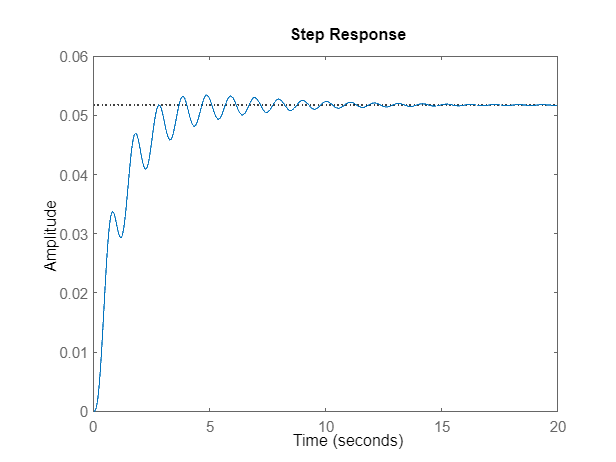

step(sys_ss, t, opts)

**Controllability and Observability**

obsy = obsv(sys_ss.A, sys_ss.C);
conty = ctrb(sys_ss.A, sys_ss.B);

if rank(obsy) == length(sys_ss.A)
    disp('The system is controllable.')
else
    disp('The system is not controllable.')
end

The system is controllable.


if rank(conty) == length(sys_ss.A)
    disp('The system is observable.')
else
    disp('The system is not observable.')
end

The system is observable.


if rank(obsy) == length(A) && rank(conty) == length(A)
    disp('This realization is minimal.')
else
    disp('This realization is not minimal.')
end

This realization is minimal.


observer_poles = [-12, -12, -12, -12];
L_t = acker(A', C', observer_poles);
L = L_t'

L =    34.4424
   64.9835
  388.2318
 -239.6876


A_obs = A-L*C

A_obs =   -34.4424         0    1.0000         0
  -64.9835         0         0    1.0000
 -379.4906   23.1436   -0.6364    2.1474
  224.3242   27.7241  -17.2553  -12.9212


B_obs = [B L] % input is [u Y]'

B_obs =          0   34.4424
         0   64.9835
    0.2919  388.2318
    7.9153 -239.6876


C_obs = eye(length(A_obs)) % since we want all the states

C_obs =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_obs = zeros(size(B_obs))

D_obs =      0     0
     0     0
     0     0
     0     0
